# SISTEMAS DE CONTROL II

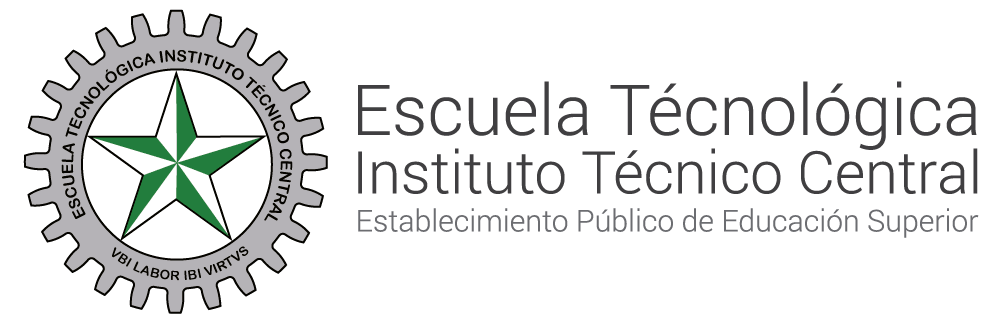

# **Transformada Z**

**Autor ** **ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c**

**Coautores:  Leidy Helena Herran Briceño, Brayan Camilo Guauta Arevalo**

## ¿Que es la transformada z ?

El metodo de la transformada Z es un metodo operacional que se utiliza para trabajar con sistemas en tiempo discreto 

La **transformada Z** se define:


$$Y\left(z\right)=Z\left\lbrack y\left(t\right)\right\rbrack =Z\left\lbrack y\left(\textrm{kT}\right)\right\rbrack =\sum_{k=0}^{\infty } y\left(\textrm{kT}\right)z^{-k}$$


Donde: 

$T:$ Es el periodo de muestreo

$y\left\lbrack k\right\rbrack :$ representa los valores de la señal discreta en instantes $k$. 

$k:$ son todos los valores de cero (0) o numeros enteros positivos 0,1,2.....($\infty$)  

Para el escalón unitario discreto se tiene **que **$u\left(k\right)=1\;\textrm{para}\;k\ge 0$**:**

### Resolver para $Y\left(z\right)=e^{-\textrm{akT}}$

Para resolver Z, se usara la serie geométrica.

Una **serie geométrica** es una suma de términos en la que cada término se obtiene multiplicando el término anterior por una constante llamada **razón** (r). La forma general de una serie geométrica es:


$$\sum_{n=0}^N r^k =\frac{r^{N+1} -1}{r-1}$$
  

Se define: 

- 
$${{e^{-a,\textrm{kT}} \cdot z}^{-k} =\left\lbrack e^{-\textrm{aT}} \cdot z^{-1} \right\rbrack }^k$$
 

- $\left(r\right)=e^{-\textrm{aT}} \cdot z^{-1}$, cambio de variable

$Y\left(z\right)=\sum_{n=0}^N r^k =\frac{r^{N+1} -1}{r-1}=\;\frac{{e^{-\textrm{aT}} \cdot z^{-1} }^{\infty +1} -1}{e^{-\textrm{aT}} \cdot z^{-1} -1}\;$, cuando $e^{-\textrm{aT}} \cdot z^{-1}$ tiende a infinito el limite es cero (0),  el resultado converge hacia $0$ $\lim_{n\longrightarrow \infty } {\left(\frac{1}{z}\right)}^n =0,\textrm{si}\;\left|\frac{1}{z}\right|<1$

$Y\left(z\right)=\frac{-1}{e^{-\textrm{aT}} \cdot \frac{1}{z}-1}\cdot \frac{-z}{-z}=\frac{z}{z-e^{-\textrm{aT}} }$, se obtiene la transformada exponencial $Y\left(z\right)=\frac{\mathit{\mathbf{z}}}{z-e^{-\textrm{aT}} }$

syms z k a T; 
assume(abs(z) > exp(-a*T));
r= exp(-a*T) * z^(-1)

$$r = \frac{{\mathrm{e}}^{-T\,a}}{z}$$

formula_serie_geometrica_exp = -1 / (r - 1)

$$formula\_serie\_geometrica\_exp = -\frac{1}{\frac{{\mathrm{e}}^{-T\,a}}{z}-1}$$

syms f(k) a T z
A=exp(-a*T*k);
F=ztrans(A)

$$F = \frac{z}{z-{\mathrm{e}}^{-T\,a}}$$

#### GRAFICA PARA LA SEGUNDA TRANSFORMADA Z $y\left\lbrack k\right\rbrack =e^{-\textrm{akT}}$

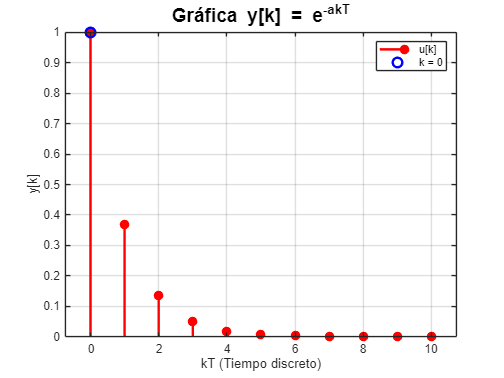

% Parámetros
a = 1; % Constante
T = 1; % Período de muestreo
k = 0:10; % Vector de tiempo discreto
% Calcular la secuencia exponencial
y = exp(-a*k*T);
% Graficar la secuencia exponencial
figure;
stem(k, y, 'filled', 'LineWidth', 2.0, 'Color', 'r'); % Representación de datos discretos
title('Gráfica y[k] = e^{-akT}', 'FontSize', 16, 'Color', 'k'); % Título
xlabel('kT (Tiempo discreto)'); % Etiqueta en x
ylabel('y[k]'); % Etiqueta en y
grid on; % Activar cuadrícula
hold on; % Conservar la gráfica actual al añadir otr
plot(0, 1, 'bo', 'MarkerSize', 8, 'LineWidth', 2); % Marcar el punto n = 0
legend('u[k]', 'k = 0');
hold off; % activa o desactiva el estado de permanencia, aqui borra o desactiva